# Jmag Express

JMAG-Express에서 각 코일에 대한 전류의 유입/유출을 표현하려면 하나의 코일을 두 개의 영역으로 나눕니다.

 하나의 코일로 구성된 두 영역을 하나의 영역으로 사용하려면 메인 창의 [와인딩] 탭의 [레이어] 풀다운 메뉴에서 [1]을 선택합니다.

% JMD - 
% JMDL
% xml

## JCF - Template Editor





jexpress.SetUserPartTemplate("stator","8p48s Wave")
app.LaunchMotorTemplate()
jexpress = actxserver(strcat('express.Application.','152'));   
jexpress.OpenUserTemplate("PM_Labproject")

jexpress.GetWriteJprojScript()
mtApp = app.CreateMotorTemplate()
mtApp.SetUserPartTemplate("stator", "8p48s Wave")
mtApp.SetProperty("SLOTS@stator@parts", 48)
mtApp.SetProperty("SLOTS@stator@parts", 72)
mtApp.SetProperty("SW1@stator@parts", 2.07)
mtApp.SetProperty("SW2@stator@parts", 3.87)
mtApp.SetProperty("SW4@stator@parts", 18.2)
mtApp.SetProperty("ST@stator@parts", 2.52)
mtApp.SetProperty("STD1@stator@parts", 5.05)
mtApp.SetProperty("SF1@stator@parts", 0.0833)
mtApp.SetProperty("SF2@stator@parts", 0.337)
mtApp.SetProperty("MC_series_number@drive_connection@drive", 24)
mtApp.SetProperty("material_conductivity@material-16@stator@parts", 64500000)
mtApp.SetProperty("material_density@material-16@stator@parts", 8960)
mtApp.SetProperty("SLOTS@stator@parts", 72)




## Exist Combination

mtApp.CreateNewCombination(,'rip_013',"8p48s Wave")
jexpress.New()
jexpress.GetComboParameterItemJson()
deGeo=jexpress.GetParameterListXML()


### Stator

jexpress.SetProperty('SLOTS@stator@parts',72)
jexpress.SetProperty('SD1@stator@parts',i_Stator_OD)
jexpress.SetProperty('SD2@stator@parts',(i_Stator_OD *i_Split_Ratio))
jexpress.SetProperty('SW1@stator @parts',36)
jexpress.SetProperty('SW2@stator @parts',36)
jexpress.SetProperty('SW4@stator @parts',36)
jexpress.SetProperty('ST@stator  @parts',36)
jexpress.SetProperty('STD1@stator@parts',36)
jexpress.SetProperty('SF1@stator @parts',36)

## Rotor

jexpress.SetProperty("RD1@ipm_rotor@parts",            (i_Stator_OD *i_Split_Ratio)-hag*2            )  
jexpress.SetProperty("RD2@ipm_rotor@parts",            Rshaft*2            )  
jexpress.SetProperty("MW1@ipm_rotor@parts",                        )  
jexpress.SetProperty("MT1@ipm_rotor@parts",                        )  
jexpress.SetProperty("DMAG1@ipm_rotor@parts",                        )
jexpress.SetProperty("MW2@ipm_rotor@parts",                        )  
jexpress.SetProperty("MT2@ipm_rotor@parts",                        )  
jexpress.SetProperty("DMAG2@ipm_rotor@parts",                        )

## 3D

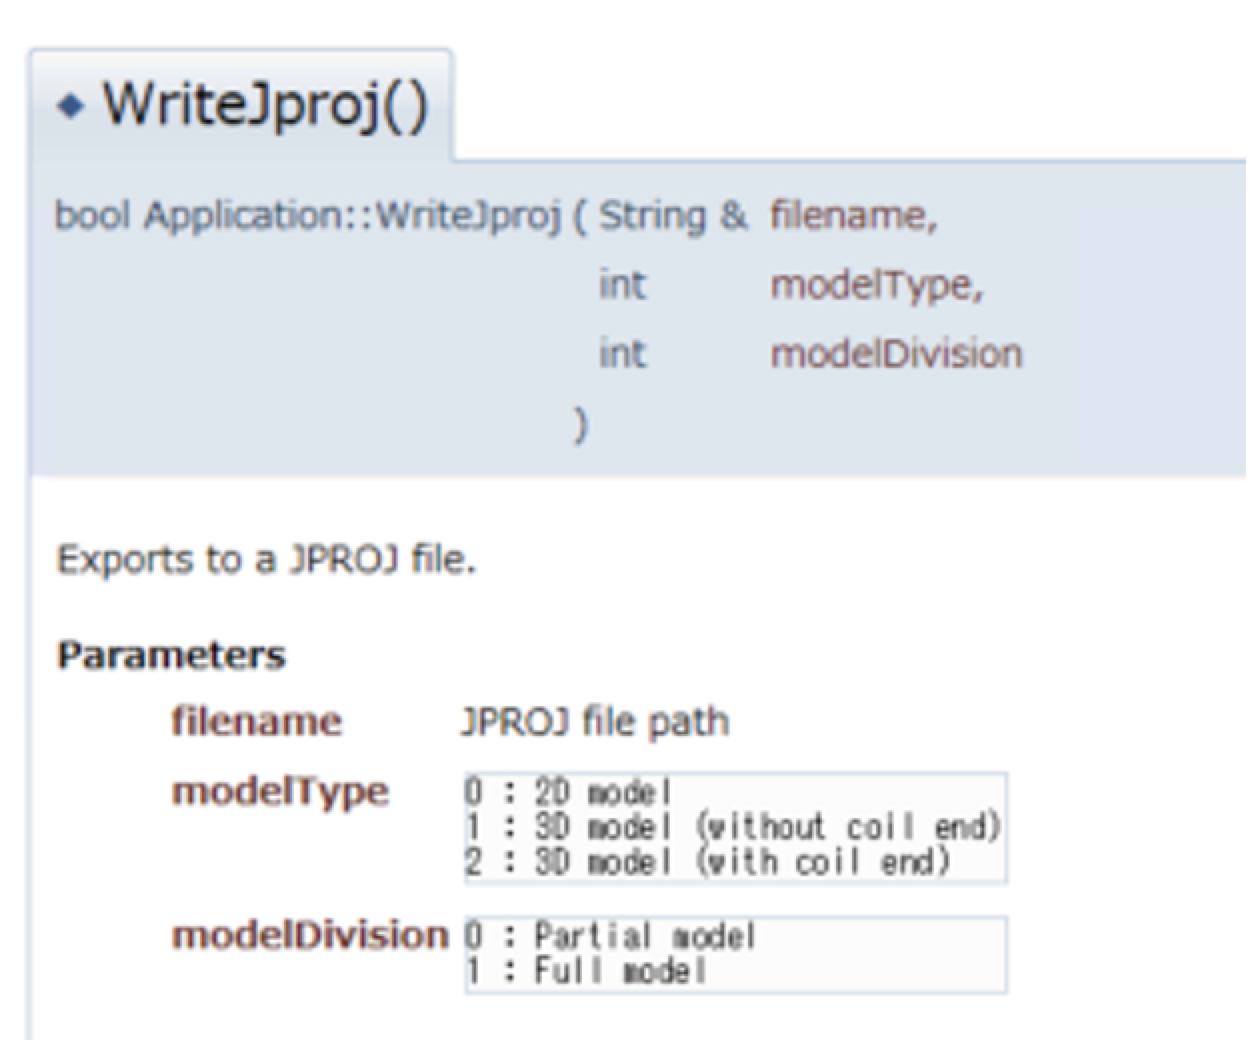

jexpress.WriteJproj(filename,2,0)